# **Feder Masse Dämpfer Schwinger:**

                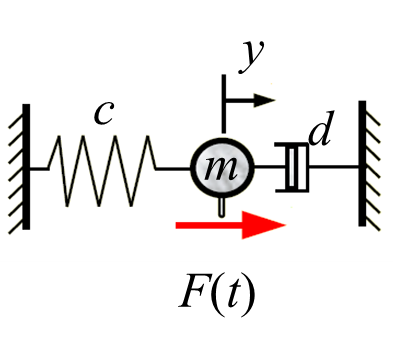

## 2. Newtonsche Gesetz:  

##                                          
$$ m \ddot y(t) + d \dot y(t)  +  c y(t) = F(t)$$


%% Definition von Masse, Ferder- und Dämpferkonstante
m = 1;
c = 1;
d = 1;
% Anmerung:
    % wenn d >> im Vergleich zu w0 -> D > 1 -> nicht schwingungsfähig
    % wenn d = 0 -> D=0 -> Dauerschwingung
    % wenn z.B. c/m ca. 1 und 0 < d < 1 -> schwingungsfähig

## Berechnung von Eigenfreqeunz (gedämpt und ungedämpft) und Dämpfung

## $D = \frac{d}{2} \sqrt{ \frac{c}{m}} $       ,     $\omega_0 = \sqrt{\frac{c}{m}}$    und    $\omega_e = \omega_0 \sqrt{1-D^2}$

%% Händische Berechnung der Eigenfreqeunz udn Dämpfung aus der Vorlesung (vgl. Folien 21-22)
w0 = sqrt(c/m)

w0 = 1

D = d/2 *w0

D = 0.5000

we = w0 * sqrt(1-D^2)

we = 0.8660


% Definition des System
s = tf('s');
G  = 1/(w0^-2*s^2 + 2*D/w0*s + 1);


## Nulstellen des charakteritischen Polynoms

## 
$$\lambda_{1,2} = \frac{-B_1 \pm \sqrt{B_1^2 - 4 B_2}}{2 B_2} 


$$


disp('Nullstellen des charakteritischen Polynoms:')

Nullstellen des charakteritischen Polynoms:


lambda1 = (-d + sqrt(d^2 - 4 * m * c)) / (2*m)

lambda1 = -0.5000 + 0.8660i

lambda2 = (-d - sqrt(d^2 - 4 * m * c)) / (2*m)

lambda2 = -0.5000 - 0.8660i


% oder via Befehl damp in Matlab (liefert neben den Eigenwerten auch gleich Freqeunz, Dämpfung und Zeitkosntanten mit)
damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.00e-01 + 8.66e-01i     5.00e-01       1.00e+00         2.00e+00    
 -5.00e-01 - 8.66e-01i     5.00e-01       1.00e+00         2.00e+00    


## Zu Erinnerung:

## 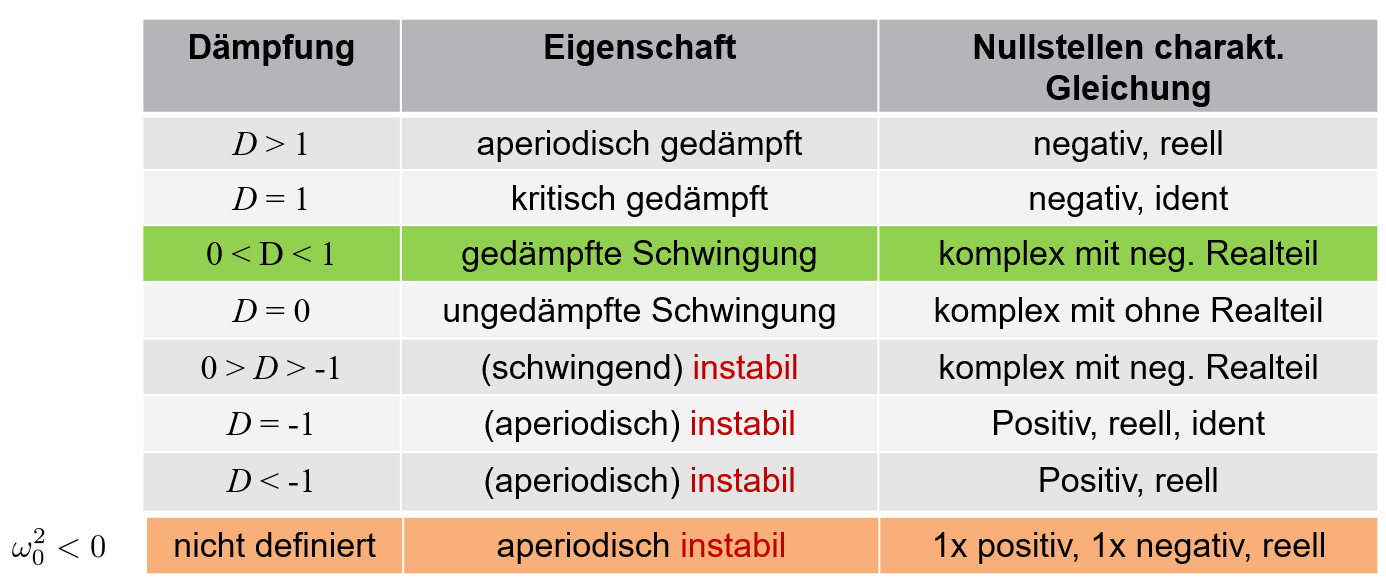

## Sprungantwort

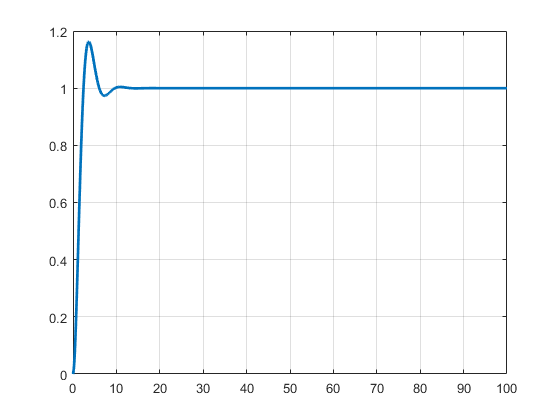

figure(1); [y,t]=step(G,100); plot(t,y); grid on; box on;

%Figure Settings
h = gca; h.Children.LineWidth =2;

## Impulsantwort

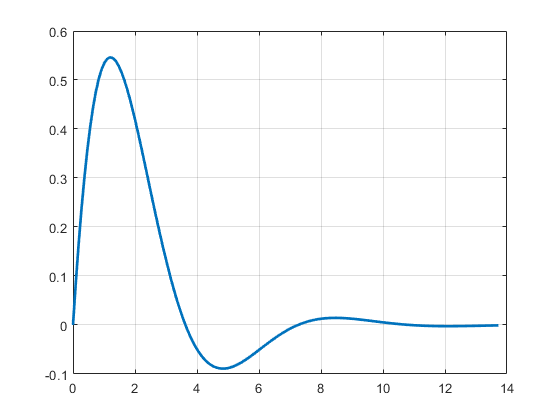

figure(2); hold on; [y,t]=impulse(G); plot(t,y); grid on; box on;
h = gca;  h.Children.LineWidth =2;